%感知机
clc;clear all;

P=[-0.5 -0.5 0.3 0;
    -0.5 0.5 -0.5 1];
%输入向量

T=[1 1 0 0];
%目标向量

%plotpv(P,T);

%初始化一个网络
net=newp([-1 1;0 1],1);
net=init(net);
y=sim(net,P)

y =      1     1     1     1


e=T-y;
w=net.iw{1,1}

w =      0     0


b=net.b{1}

b = 0

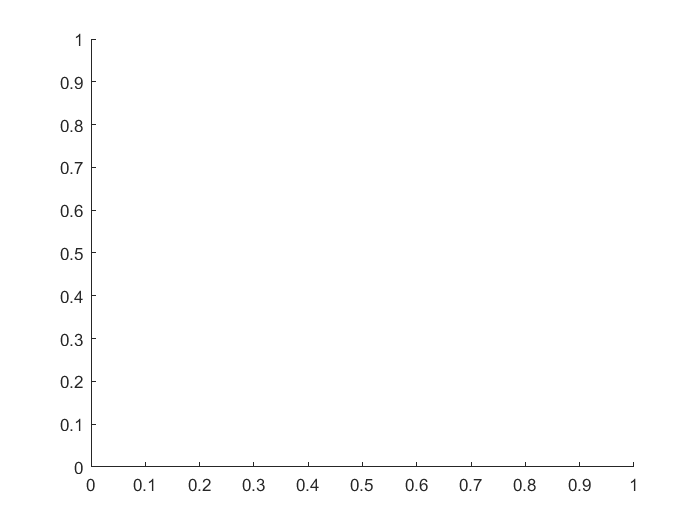

plotpc(w,b)
while (mae(e)>0.0015)
    dw=learnp(w,P,[],[],[],[],e,[],[],[],[],[]);
    db=learnp(b,ones(1,4),[],[],[],[],e,[],[],[],[],[]);
    %调整
    w=w+dw;
    b=b+db;
    net.iw{1,1}=w;
    net.b{1}=b;
    plotpc(w,b)
    pause;
    y=sim(net,P);
    e=T-y;
end

disp('运行结束！')